clear all;
close all;

Load the data. Make sure you have the directory containing the file in your MATLAB path. This provides two variable "xs" and "data" (the x-values and y-values). 

load("Quiz3.mat")
ys = data; % In case you like "y" better than "data"

You can visualize the data.

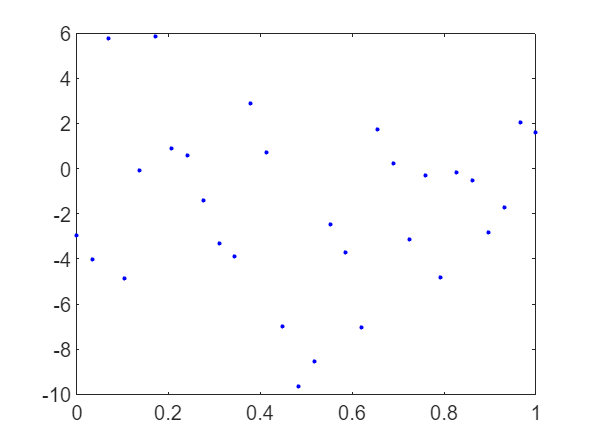

fig1 = figure(1);
clf(fig1,"reset");
plot(xs, data, ".b");
hold on;

Build the the [matrix $A$](https://en.wikipedia.org/wiki/Design_matrix) whose column space we are trying to minimize the distance to.

% Enter your "design" matrix. 
A = [ones(size(xs)) xs xs.^2 sqrt(xs)];

Find the least-square solution to $Ax=\text{data}$

% Enter an expression providing a least squares solution to Ax = ys
xhat = A\ys

xhat =    -4.0425
  -70.6405
   39.8049
   36.6561


Compute the element in $\text{CS}(A)$ closest to the data.

% Enter an expression that computes the projection of the data (ys) onto
% CS(A). This is the values your molde predicts at the xs.
yhat = A*xhat;

Enter the function you have computed:


$$f(x)= -4 - 70.6x + 39.8x^2 +36.7\sqrt{x}$$


Add your model to the plot.

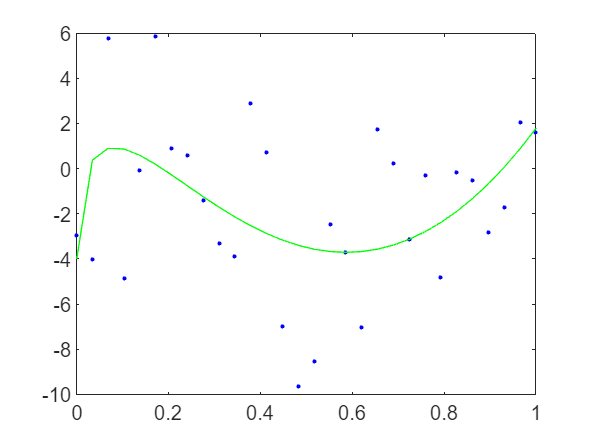

plot(xs, yhat, "-g"); 

Do not edit below here.

function n = replaceMe()
    display('You must replace this with your answer');
    n = 0;
end